%% 1. Load Foshan data once and configure the workflow
% Use a dedicated variable to avoid accidentally reusing Tianjin data.
% Subsequent runs reuse foshanRaw without loading the file again.
% Preprocess all sensors, then model one selected static sensor.
% These are exploratory rolling comparisons, not an independent final test.

if ~exist('foshanRaw', 'var')
    foshanRaw = load( ...
        '/Users/yuanyang/Downloads/short_term_foshan_train_val.mat', ...
        'data_static', 'data_mobile');
end

sensorIndex = 1;
historyDays = 3;
horizonMinutes = 180;
trainingOriginStepMinutes = 60;

outputFolder = ...
    '/Users/yuanyang/Documents/Codex/2026-10-21/he/outputs';


%% 2. Clean static and mobile sensor observations
% Remove missing timestamps, sort records, and convert nonfinite numbers
% to NaN. Preserve finite PM2.5 peaks without assuming sensor error.
% Mark invalid GPS coordinates as missing.
% Report duplicates and gaps; do not interpolate or forward-fill.
% Mobile observations retain their original positions and timestamps.

staticClean = cell(size(foshanRaw.data_static));
mobileClean = cell(size(foshanRaw.data_mobile));
quality = table();

groups = {'data_static', 'data_mobile'};

for g = 1:numel(groups)
    source = foshanRaw.(groups{g});

    for i = 1:numel(source)
        [T, q] = cleanSensor(source{i});
        q.SensorTable = string(sprintf('%s{%d}', groups{g}, i));

        if isempty(quality)
            quality = q;
        else
            quality = [quality; q];
        end

        if g == 1
            staticClean{i} = T;
        else
            mobileClean{i} = T;
        end
    end
end


%% 3. Create one-minute static sensor signals
% Average each sensor separately and retain counts for each variable.
% Empty minute bins remain NaN. No minimum count threshold is imposed.
% A bin labeled 12:00 summarizes [12:00, 12:01) and becomes fully available
% at 12:01. This availability time prevents using unfinished bins.
% Mobile data are not averaged because their locations change.

static1min = cell(size(staticClean));
variables = {'pm2d5', 'tmp', 'hmd', 'spd'};

for i = 1:numel(staticClean)
    T = staticClean{i};

    if isempty(T)
        continue;
    end

    TT = table2timetable( ...
        T(:, [{'time'}, variables]), 'RowTimes', 'time');

    firstBin = dateshift(T.time(1), 'start', 'minute');
    lastBin = dateshift(T.time(end), 'start', 'minute');
    minuteGrid = (firstBin:minutes(1):lastBin)';

    A = retime(TT, minuteGrid, @(x) mean(x, 'omitnan'));
    N = retime(TT, minuteGrid, @(x) sum(isfinite(x)));

    A.Properties.DimensionNames{1} = 'Time';

    for j = 1:numel(variables)
        name = variables{j};
        count = N.(name);
        count(~isfinite(count)) = 0;

        A.(['n_' name]) = count;
        A.(name)(count == 0) = NaN;
    end

    A.lat = repmat(median(T.lat, 'omitnan'), height(A), 1);
    A.lon = repmat(median(T.lon, 'omitnan'), height(A), 1);
    A.SensorIndex = repmat(i, height(A), 1);
    A.AvailableTime = A.Properties.RowTimes + minutes(1);

    static1min{i} = A;
end


%% 4. Define rolling short-term forecast windows
% Use the preceding three days for each model fit.
% Forecast the following three hours, then advance three hours.
% Historical training origins are spaced hourly to limit computation.
% Each origin provides training targets at one-minute lead times.
% Only complete forecast time ranges within the dataset are included.

A = static1min{sensorIndex};

if isempty(A)
    error('The selected static sensor has no processed observations.');
end

t = A.Properties.RowTimes;
availableAt = A.AvailableTime;

if any(diff(t) ~= minutes(1))
    error('A regular one-minute time grid is required.');
end

firstForecast = t(1) + days(historyDays);
dataEnd = t(end) + minutes(1);
lastForecast = dataEnd - minutes(horizonMinutes);

forecastStarts = ...
    (firstForecast:minutes(horizonMinutes):lastForecast)';

if isempty(forecastStarts)
    error('Not enough data for a complete forecast window.');
end

modelsLatest = cell(numel(forecastStarts), 1);
forecastParts = cell(numel(forecastStarts), 1);
nTrainingPairs = zeros(numel(forecastStarts), 1);

predictorNames = ...
    {'LatestPM25', 'Temperature', 'Humidity', ...
     'LeadMinutes', 'TargetHour'};


%% 5. Build training examples and fit each rolling model
% Inputs are source-minute PM2.5, temperature, humidity, forecast lead time,
% and target hour. Training targets and inputs stay within the history window.
% A historical origin occurs when its source minute finishes.
% Missing training pairs are excluded without interpolation.
% Each model is refitted independently using only information available
% by the actual forecast start.

for k = 1:numel(forecastStarts)

    cutoff = forecastStarts(k);
    trainStart = cutoff - days(historyDays);

    eligibleSources = find( ...
        t >= trainStart & availableAt < cutoff);

    origins = ...
        (eligibleSources(1):trainingOriginStepMinutes: ...
         eligibleSources(end))';

    [originIndex, lead] = ndgrid(origins, 1:horizonMinutes);

    originIndex = originIndex(:);
    lead = lead(:);
    targetIndex = originIndex + lead;

    insideData = targetIndex <= height(A);
    originIndex = originIndex(insideData);
    targetIndex = targetIndex(insideData);
    lead = lead(insideData);

    insideHistory = availableAt(targetIndex) <= cutoff;
    originIndex = originIndex(insideHistory);
    targetIndex = targetIndex(insideHistory);
    lead = lead(insideHistory);

    Xtrain = [ ...
        A.pm2d5(originIndex), ...
        A.tmp(originIndex), ...
        A.hmd(originIndex), ...
        lead, ...
        hour(t(targetIndex)) + minute(t(targetIndex))/60];

    ytrain = A.pm2d5(targetIndex);

    usable = all(isfinite(Xtrain), 2) & isfinite(ytrain);
    nTrainingPairs(k) = sum(usable);


    %% 6. Generate regression and persistence forecasts
    % Select the latest valid PM2.5 bin completed by forecast start.
    % Use temperature and humidity from that same bin.
    % Hold these observations fixed during the entire three-hour forecast.
    % Persistence uses the same latest PM2.5 value.
    % Record measurement age; this baseline does not explicitly model age.
    % Missing weather inputs leave regression predictions as NaN.

    futureIndex = find( ...
        t >= cutoff & ...
        t < cutoff + minutes(horizonMinutes));

    targetTime = t(futureIndex);

    F = table( ...
        repmat(cutoff, numel(futureIndex), 1), ...
        targetTime, ...
        NaN(numel(futureIndex), 1), ...
        NaN(numel(futureIndex), 1), ...
        NaN(numel(futureIndex), 1), ...
        'VariableNames', ...
        {'ForecastStart', 'TargetTime', 'LinearPM25', ...
         'PersistencePM25', 'MeasurementAgeMinutes'});

    latest = find( ...
        t >= trainStart & availableAt <= cutoff & ...
        isfinite(A.pm2d5), 1, 'last');

    if isempty(latest)
        warning('Window %d: no available PM2.5 measurement.', k);
        forecastParts{k} = F;
        continue;
    end

    F.PersistencePM25(:) = A.pm2d5(latest);
    F.MeasurementAgeMinutes(:) = ...
        minutes(cutoff - availableAt(latest));

    Xfuture = [ ...
        repmat(A.pm2d5(latest), numel(futureIndex), 1), ...
        repmat(A.tmp(latest), numel(futureIndex), 1), ...
        repmat(A.hmd(latest), numel(futureIndex), 1), ...
        minutes(availableAt(futureIndex) - cutoff), ...
        hour(targetTime) + minute(targetTime)/60];

    if nTrainingPairs(k) > size(Xtrain, 2) + 1

        trainingTable = array2table( ...
            Xtrain(usable,:), 'VariableNames', predictorNames);
        trainingTable.PM25 = ytrain(usable);

        model = fitlm(trainingTable, ...
            ['PM25 ~ LatestPM25 + Temperature + Humidity + ' ...
             'LeadMinutes + TargetHour']);

        modelsLatest{k} = model;

        good = all(isfinite(Xfuture), 2);

        if any(good)
            futureTable = array2table( ...
                Xfuture(good,:), 'VariableNames', predictorNames);
            F.LinearPM25(good) = predict(model, futureTable);
        end

    else
        warning('Window %d: insufficient training pairs.', k);
    end

    forecastParts{k} = F;
end

latestForecasts = vertcat(forecastParts{:});


%% 7. Match predictions to observations and compare errors
% Retrieve actual forecast targets only after predictions are generated.
% Compare both methods on identical valid observations.
% RMSE emphasizes large errors; MAE measures average absolute error.
% Bias is predicted minus observed. No NRMSE normalization is assumed.

[matched, row] = ismember(latestForecasts.TargetTime, t);

actual = NaN(height(latestForecasts), 1);
actual(matched) = A.pm2d5(row(matched));
latestForecasts.ActualPM25 = actual;

compare = isfinite(actual) & ...
    isfinite(latestForecasts.LinearPM25) & ...
    isfinite(latestForecasts.PersistencePM25);

if ~any(compare)
    error('No common valid observations are available for evaluation.');
end

errorLinear = latestForecasts.LinearPM25(compare) - actual(compare);
errorPersistence = ...
    latestForecasts.PersistencePM25(compare) - actual(compare);

Method = ["Linear: latest measurement + lead time"; "Persistence"];

RMSE = [sqrt(mean(errorLinear.^2)); ...
        sqrt(mean(errorPersistence.^2))];

MAE = [mean(abs(errorLinear)); ...
       mean(abs(errorPersistence))];

Bias = [mean(errorLinear); mean(errorPersistence)];

overallComparison = table(Method, RMSE, MAE, Bias);
disp(overallComparison);

                     Method                      RMSE      MAE        Bias   
    ________________________________________    ______    ______    _________

    "Linear: latest measurement + lead time"    8.3486    4.9853    -0.076678
    "Persistence"                               7.4749    4.3486      0.68085





%% 8. Calculate errors separately for each forecast window
% Use the same common-observation mask as the pooled comparison.
% EvaluatedMinutes records how many predictions contribute to each score.

linearRMSE = NaN(numel(forecastStarts), 1);
persistenceRMSE = NaN(numel(forecastStarts), 1);
evaluatedMinutes = zeros(numel(forecastStarts), 1);

for k = 1:numel(forecastStarts)

    use = compare & ...
        latestForecasts.ForecastStart == forecastStarts(k);

    evaluatedMinutes(k) = sum(use);

    if any(use)
        eLinear = latestForecasts.LinearPM25(use) - actual(use);
        ePersistence = ...
            latestForecasts.PersistencePM25(use) - actual(use);

        linearRMSE(k) = sqrt(mean(eLinear.^2));
        persistenceRMSE(k) = sqrt(mean(ePersistence.^2));
    end
end

windowComparison = table( ...
    forecastStarts, nTrainingPairs, evaluatedMinutes, ...
    linearRMSE, persistenceRMSE, ...
    'VariableNames', ...
    {'ForecastStart', 'TrainingPairs', 'EvaluatedMinutes', ...
     'LinearRMSE', 'PersistenceRMSE'});

disp(windowComparison);

       ForecastStart       TrainingPairs    EvaluatedMinutes    LinearRMSE    PersistenceRMSE
    ___________________    _____________    ________________    __________    _______________

    2018-10-11 00:00:00        12777              180             7.4698            8.277    
    2018-10-11 03:00:00        12777              180             1.4844           3.2364    
    2018-10-11 06:00:00        12777              180             5.2727           2.9172    
    2018-10-11 09:00:00        12777              180              11.24           7.5837    
    2018-10-11 12:00:00        12777              180             5.9755           2.1875    
    2018-10-11 15:00:00        12777              180             6.2537           4.5527    
    2018-10-11 18:00:00        12777              180            0.99329     

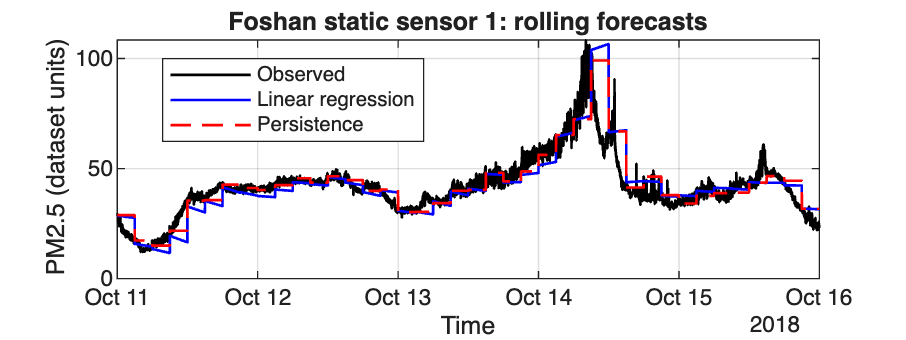



%% 9. Plot actual measurements and both forecast signals
% Every three-hour segment uses a separately fitted regression model.
% Persistence updates at forecast start and stays constant within the window.
% These lines show minute-bin averages, not individual raw measurements.

figure('Color', 'w', 'Position', [100 100 1200 450]);

plot(latestForecasts.TargetTime, actual, ...
    'k', 'LineWidth', 1);
hold on;

plot(latestForecasts.TargetTime, latestForecasts.LinearPM25, ...
    'b', 'LineWidth', 1);

plot(latestForecasts.TargetTime, latestForecasts.PersistencePM25, ...
    '--r', 'LineWidth', 1);

xlabel('Time');
ylabel('PM2.5 (dataset units)');
title(sprintf('Foshan static sensor %d: rolling forecasts', sensorIndex));
legend('Observed', 'Linear regression', 'Persistence', ...
    'Location', 'best');
grid on;

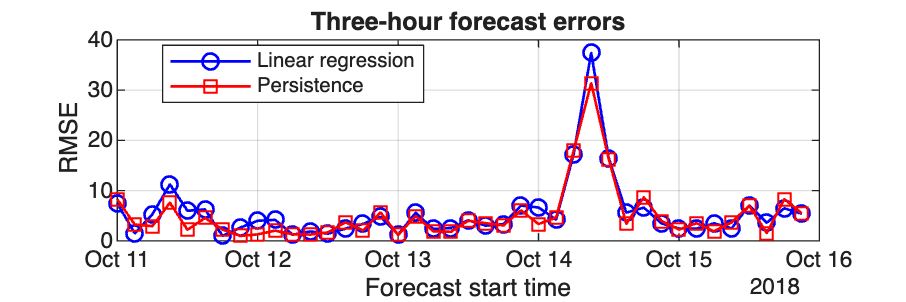



%% 10. Plot forecast errors across windows
% Lower RMSE indicates better accuracy on the shared evaluated observations.

figure('Color', 'w', 'Position', [100 100 1200 400]);

plot(forecastStarts, linearRMSE, '-ob', 'LineWidth', 1);
hold on;
plot(forecastStarts, persistenceRMSE, '-sr', 'LineWidth', 1);

xlabel('Forecast start time');
ylabel('RMSE');
title('Three-hour forecast errors');
legend('Linear regression', 'Persistence', 'Location', 'best');
grid on;



%% 11. Save preprocessing and modeling results separately
% Preserve original data files. Save settings alongside the outputs.
% Cleaned mobile observations are retained but are not regression inputs.
% fitlm requires Statistics and Machine Learning Toolbox.

if ~exist(outputFolder, 'dir')
    mkdir(outputFolder);
end

settings = struct( ...
    'Dataset', "Foshan short-term", ...
    'SensorIndex', sensorIndex, ...
    'BinMinutes', 1, ...
    'HistoryDays', historyDays, ...
    'HorizonMinutes', horizonMinutes, ...
    'TrainingOriginStepMinutes', trainingOriginStepMinutes);

save(fullfile(outputFolder, 'foshan_preprocessed.mat'), ...
    'settings', 'quality', 'staticClean', 'mobileClean', ...
    'static1min', '-v7.3');

save(fullfile(outputFolder, 'foshan_latest_baseline.mat'), ...
    'settings', 'forecastStarts', 'modelsLatest', ...
    'latestForecasts', 'overallComparison', ...
    'windowComparison', '-v7.3');


%% Local function: clean one sensor table and summarize quality
% Keep individual missing measurements as NaN.
% Duplicate timestamps are reported, not automatically deleted.
% The six-second threshold identifies intervals for inspection;
% it does not establish that a device failed.

function [T, q] = cleanSensor(T)

    rawRows = height(T);
    missingTimes = sum(isnat(T.time));
    T = sortrows(T(~isnat(T.time), :), 'time');

    names = T.Properties.VariableNames;

    for j = 1:numel(names)
        if isnumeric(T.(names{j}))
            values = double(T.(names{j}));
            values(~isfinite(values)) = NaN;
            T.(names{j}) = values;
        end
    end

    invalidGPS = ...
        ~isfinite(T.lat) | ~isfinite(T.lon) | ...
        abs(T.lat) > 90 | abs(T.lon) > 180 | ...
        (T.lat == 0 & T.lon == 0);

    T.lat(invalidGPS) = NaN;
    T.lon(invalidGPS) = NaN;

    dt = seconds(diff(T.time));

    longestInterval = NaN;
    if ~isempty(dt)
        longestInterval = max(dt);
    end

    q = table( ...
        rawRows, height(T), missingTimes, ...
        sum(dt == 0), sum(dt > 6), longestInterval, ...
        sum(isnan(T.pm2d5)), sum(invalidGPS), ...
        'VariableNames', ...
        {'RawRows', 'CleanRows', 'MissingTimestamps', ...
         'DuplicateTimestamps', 'IntervalsOver6Seconds', ...
         'LongestIntervalSeconds', 'MissingPM25', 'InvalidGPSRows'});
end

%% 1. Configure the trend experiment
% Reuse the processed data without loading anything.
% Compare the original latest-measurement regression, regression with
% a 30-minute trend, and persistence.
% Use three-day rolling training windows and three-hour forecasts.
% Results are exploratory comparisons, not independent final test scores.

Atrend = static1min{sensorIndex};
trendTime = Atrend.Properties.RowTimes;
trendAvailable = Atrend.AvailableTime;

trendLookback = 30;
trendHorizon = 180;
trendHistoryDays = 3;
trendOriginStep = 60;

if any(diff(trendTime) ~= minutes(1))
    error('A regular one-minute time grid is required.');
end

trendStarts = ( ...
    trendTime(1) + days(trendHistoryDays):minutes(trendHorizon): ...
    trendTime(end) + minutes(1) - minutes(trendHorizon))';

if isempty(trendStarts)
    error('Not enough data for a complete forecast window.');
end

trendParts = cell(numel(trendStarts), 1);


%% 2. Build shared historical training examples
% Both regressions use exactly the same training observations.
% The original inputs are latest PM2.5, temperature, humidity, lead time,
% and target hour.
% The added predictor is the past 30-minute PM2.5 slope multiplied by lead.
% Both trend endpoints and training targets stay within the history window.
% The slope uses two endpoints; it does not interpolate missing observations.

for k = 1:numel(trendStarts)

    cutoff = trendStarts(k);
    trainStart = cutoff - days(trendHistoryDays);

    eligible = find( ...
        trendTime >= trainStart + minutes(trendLookback) & ...
        trendAvailable < cutoff);

    if isempty(eligible)
        error('No training origins available for window %d.', k);
    end

    origins = (eligible(1):trendOriginStep:eligible(end))';

    [source, lead] = ndgrid(origins, 1:trendHorizon);
    source = source(:);
    lead = lead(:);
    target = source + lead;

    keep = target <= height(Atrend);
    source = source(keep);
    target = target(keep);
    lead = lead(keep);

    keep = trendAvailable(target) <= cutoff;
    source = source(keep);
    target = target(keep);
    lead = lead(keep);

    slope = (Atrend.pm2d5(source) - ...
        Atrend.pm2d5(source-trendLookback)) / trendLookback;

    Xoriginal = [ ...
        Atrend.pm2d5(source), ...
        Atrend.tmp(source), ...
        Atrend.hmd(source), ...
        lead, ...
        hour(trendTime(target)) + minute(trendTime(target))/60];

    XwithTrend = [Xoriginal, slope .* lead];
    trainingTarget = Atrend.pm2d5(target);

    sharedTrain = all(isfinite(XwithTrend), 2) & ...
        isfinite(trainingTarget);


    %% 3. Prepare predictions from the actual forecast origin
    % Use the latest valid PM2.5 available before forecasting begins.
    % Weather comes from that same minute.
    % Require a valid reading exactly 30 minutes before the source reading.
    % If the latest reading is stale, use elapsed time since that reading
    % for the trend contribution. Record its age for later inspection.
    % No actual future PM2.5 or future weather is used as an input.

    future = find( ...
        trendTime >= cutoff & ...
        trendTime < cutoff + minutes(trendHorizon));

    Ftrend = table( ...
        repmat(cutoff, numel(future), 1), ...
        trendTime(future), ...
        NaN(numel(future), 1), ...
        NaN(numel(future), 1), ...
        NaN(numel(future), 1), ...
        NaN(numel(future), 1), ...
        'VariableNames', ...
        {'ForecastStart','TargetTime','OriginalLinear', ...
         'TrendLinear','Persistence','MeasurementAgeMinutes'});

    latest = find( ...
        trendTime >= trainStart & ...
        trendAvailable <= cutoff & ...
        isfinite(Atrend.pm2d5), 1, 'last');

    if isempty(latest)
        trendParts{k} = Ftrend;
        continue;
    end

    Ftrend.Persistence(:) = Atrend.pm2d5(latest);

    measurementAge = minutes(cutoff - trendAvailable(latest));
    Ftrend.MeasurementAgeMinutes(:) = measurementAge;

    if latest <= trendLookback || ...
            trendTime(latest-trendLookback) < trainStart || ...
            sum(sharedTrain) <= size(XwithTrend, 2) + 1

        trendParts{k} = Ftrend;
        continue;
    end

    slopeNow = (Atrend.pm2d5(latest) - ...
        Atrend.pm2d5(latest-trendLookback)) / trendLookback;

    forecastLead = minutes(trendAvailable(future) - cutoff);

    futureOriginal = [ ...
        repmat(Atrend.pm2d5(latest), numel(future), 1), ...
        repmat(Atrend.tmp(latest), numel(future), 1), ...
        repmat(Atrend.hmd(latest), numel(future), 1), ...
        forecastLead, ...
        hour(trendTime(future)) + minute(trendTime(future))/60];

    futureWithTrend = [ ...
        futureOriginal, slopeNow .* (forecastLead + measurementAge)];


    %% 4. Fit both regressions and predict on shared valid inputs
    % Refit the original regression on the same rows as the trend model.
    % The added trend remains a linear predictor with a fitted coefficient;
    % the model does not assume that the recent trend continues unchanged.
    % Missing inputs leave predictions as NaN.

    originalModel = fitlm( ...
        Xoriginal(sharedTrain,:), trainingTarget(sharedTrain));

    withTrendModel = fitlm( ...
        XwithTrend(sharedTrain,:), trainingTarget(sharedTrain));

    sharedFuture = all(isfinite(futureWithTrend), 2);

    if any(sharedFuture)
        Ftrend.OriginalLinear(sharedFuture) = predict( ...
            originalModel, futureOriginal(sharedFuture,:));

        Ftrend.TrendLinear(sharedFuture) = predict( ...
            withTrendModel, futureWithTrend(sharedFuture,:));
    end

    trendParts{k} = Ftrend;
end

trendResults = vertcat(trendParts{:});


%% 5. Retrieve observations and calculate pooled errors
% Evaluate all methods on exactly the same valid targets.
% RMSE emphasizes large errors; MAE measures absolute errors.
% Bias is predicted minus observed.
% The original model's scores may differ from earlier results because
% this comparison uses shared trend-compatible training and evaluation rows.

[matched, location] = ismember( ...
    trendResults.TargetTime, trendTime);

trendActual = NaN(height(trendResults), 1);
trendActual(matched) = Atrend.pm2d5(location(matched));
trendResults.ActualPM25 = trendActual;

trendPredictions = [ ...
    trendResults.OriginalLinear, ...
    trendResults.TrendLinear, ...
    trendResults.Persistence];

sharedEvaluation = isfinite(trendActual) & ...
    all(isfinite(trendPredictions), 2);

if ~any(sharedEvaluation)
    error('No common valid observations are available.');
end

trendErrors = trendPredictions(sharedEvaluation,:) - ...
    trendActual(sharedEvaluation);

Method = ["Original latest-measurement linear"; ...
          "Linear with 30-minute trend"; ...
          "Persistence"];

RMSE = sqrt(mean(trendErrors.^2, 1))';
MAE = mean(abs(trendErrors), 1)';
Bias = mean(trendErrors, 1)';

trendErrorComparison = table(Method, RMSE, MAE, Bias);
disp(trendErrorComparison);

                   Method                    RMSE      MAE        Bias  
    ____________________________________    ______    ______    ________

    "Original latest-measurement linear"    8.6674    5.1825    -0.38275
    "Linear with 30-minute trend"           8.9319    5.6255     -0.4152
    "Persistence"                           7.4749    4.3486     0.68085




fprintf('Common evaluated minutes: %d\n', sum(sharedEvaluation));

Common evaluated minutes: 7199




%% 6. Calculate RMSE for each forecast window
% Restrict every window to the same shared evaluation observations.
% A window with no shared predictions receives NaN scores.

windowRMSE = NaN(numel(trendStarts), 3);
windowMinutes = zeros(numel(trendStarts), 1);

for k = 1:numel(trendStarts)

    use = sharedEvaluation & ...
        trendResults.ForecastStart == trendStarts(k);

    windowMinutes(k) = sum(use);

    if any(use)
        windowErrors = trendPredictions(use,:) - trendActual(use);
        windowRMSE(k,:) = sqrt(mean(windowErrors.^2, 1));
    end
end

trendWindowComparison = table( ...
    trendStarts, windowMinutes, ...
    windowRMSE(:,1), windowRMSE(:,2), windowRMSE(:,3), ...
    'VariableNames', ...
    {'ForecastStart','EvaluatedMinutes','OriginalLinearRMSE', ...
     'TrendLinearRMSE','PersistenceRMSE'});

disp(trendWindowComparison);

       ForecastStart       EvaluatedMinutes    OriginalLinearRMSE    TrendLinearRMSE    PersistenceRMSE
    ___________________    ________________    __________________    _______________    _______________

    2018-10-11 00:00:00          180                 6.9291              7.0414               8.277    
    2018-10-11 03:00:00          180                 1.9533              1.7686              3.2364    
    2018-10-11 06:00:00          180                 5.1023               6.171              2.9172    
    2018-10-11 09:00:00          180                  12.16              13.306              7.5837    
    2018-10-11 12:00:00          180                 7.7643              7.8941              2.1875    
    2018-10-11 15:00:00          180                 7.2772              6.9208              4.5527  

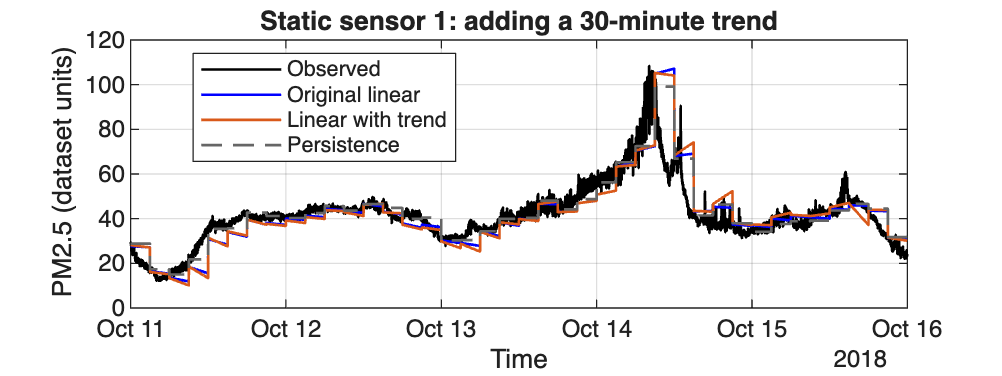



%% 7. Plot actual PM2.5 and predictions
% Show the full observation signal.
% Display predictions only at the shared evaluation times so that the
% visual comparison uses the same targets as the error table.

plotPredictions = trendPredictions;
plotPredictions(~sharedEvaluation,:) = NaN;

figure('Color','w', 'Position',[100 100 1200 450]);

plot(trendResults.TargetTime, trendActual, ...
    'k', 'LineWidth',1);
hold on;

plot(trendResults.TargetTime, plotPredictions(:,1), ...
    'b', 'LineWidth',1);

plot(trendResults.TargetTime, plotPredictions(:,2), ...
    'Color',[0.85 0.35 0.10], 'LineWidth',1);

plot(trendResults.TargetTime, plotPredictions(:,3), ...
    '--', 'Color',[0.4 0.4 0.4], 'LineWidth',1);

xlabel('Time');
ylabel('PM2.5 (dataset units)');
title(sprintf('Static sensor %d: adding a 30-minute trend', sensorIndex));

legend('Observed','Original linear','Linear with trend', ...
    'Persistence','Location','best');
grid on;

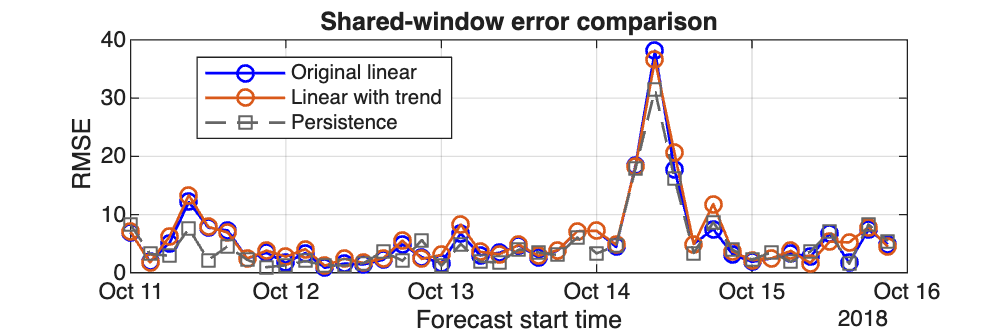



%% 8. Plot RMSE across forecast windows
% Check whether any improvement is consistent across windows rather
% than relying only on one pooled score.

figure('Color','w', 'Position',[100 100 1200 400]);

plot(trendStarts, windowRMSE(:,1), '-ob', 'LineWidth',1);
hold on;

plot(trendStarts, windowRMSE(:,2), '-o', ...
    'Color',[0.85 0.35 0.10], 'LineWidth',1);

plot(trendStarts, windowRMSE(:,3), '--s', ...
    'Color',[0.4 0.4 0.4], 'LineWidth',1);

xlabel('Forecast start time');
ylabel('RMSE');
title('Shared-window error comparison');

legend('Original linear','Linear with trend','Persistence', ...
    'Location','best');
grid on;

% Cleaning: Removed records without timestamps, sorted observations, converted nonfinite values to missing values, and flagged invalid GPS coordinates. 
%           We retained high PM2.5 readings and left gaps unfilled.
% Signal processing: Averaged each static sensor's measurements into one-minute bins, retaining observation counts. 
%                   Additional five-minute smoothing showed no improvement in the earlier fixed-lag experiment, so we kept one-minute averaging.
% Linear regression: For static sensor 1, used the latest available PM2.5, temperature, humidity, forecast lead time, and target time of day. 
%                    We retrained on rolling three-day histories to forecast the following three hours.
% Persistence baseline: Predicted the latest available PM2.5 value throughout each three-hour window.
% Preliminary results: Latest-measurement linear regression achieved RMSE 8.35, compared with 7.47 for persistence. 
%                      Adding a 30-minute trend did not improve performance in a separate matched comparison.